# **Lab4 DOF Pendulum**

Name: Zhu Chenhao

HDU ID: 22320630

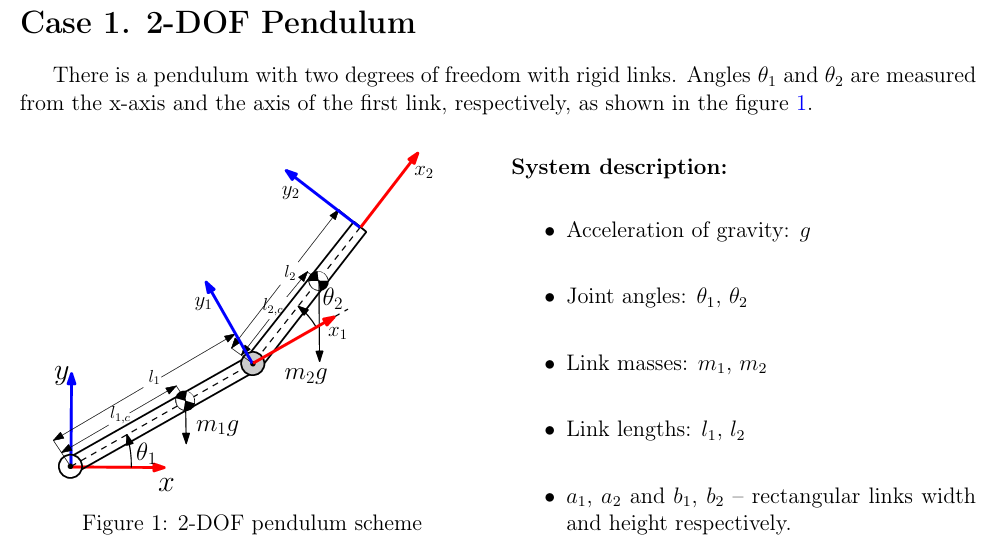

hwc = hwc_connect('https://dss2025.hdu.vedyakov.com');

Connection established


task = hwc.get_task(4);

## Initial Data

task.parameters

ans = 包含以下字段的 struct :
              a1: 0.1695
              a2: 0.0862
              b1: 0.0623
              b2: 0.0647
               g: [3×1 double]
    initialTheta: [2×1 double]
              l1: 1.3453
              l2: 2.5323
              m1: 3.4819
              m2: 4.3600


a1 = 0.1695;
b1 = 0.0623;
l1 = 1.3453;
m1 = 3.4819; 
a2 = 0.0862;
b2 = 0.0647;
l2 = 2.5323;
m2 = 4.3600;
g = [0;-9.82000;0];
initialTheta = [-0.804197861029562;-0.226490079971473];

## Calculation


$$\begin{array}{l}
x_1 =\frac{l_1 }{2}\sin (\theta_1 )\\
y_1 =-\frac{l_1 }{2}\cos (\theta_1 )\\
x_2 =l_1 \sin (\theta_1 )+\frac{l_2 }{2}\sin (\theta_2 )\\
y_2 =-l_1 \cos (\theta_1 )+\frac{l_2 }{2}\cos (\theta_2 )\\
{\dot{x} }_1 =\frac{l_1 }{2}\cos (\theta_1 )\cdot {\dot{\theta} }_1 \\
{\dot{y} }_1 =\frac{l_1 }{2}\sin (\theta_1 )\cdot {\dot{\theta} }_1 \\
{\dot{x} }_2 =l_1 \cos (\theta_1 )\cdot {\dot{\theta} }_1 +\frac{l_2 }{2}\cos (\theta_2 )\cdot {\dot{\theta} }_2 \\
{\dot{y} }_2 =l_1 \sin (\theta_1 )\cdot {\dot{\theta} }_1 -\frac{l_2 }{2}\sin (\theta_2 )\cdot {\dot{\theta} }_2 \\
I_1 =\frac{1}{12}m_1 (a_1^2 +l_1^2 )\\
I_2 =\frac{1}{12}m_2 (a_2^2 +l_2^2 )\\
K_1 =\frac{1}{2}\left(m_1 {\left(\frac{l_1 }{2}\right)}^2 +I_1 \right){\dot{\theta} }_1^2 \\
K_2 =\frac{1}{2}m_2 \left\lbrack \left(l_1^2 +{\left(\frac{l_2 }{2}\right)}^2 +l_1 l_2 \cos (\theta_2 )\right){\dot{\theta} }_1^2 +2\left({\left(\frac{l_2 }{2}\right)}^2 +\frac{l_1 l_2 }{2}\cos (\theta_2 )\right){\dot{\theta} }_1 {\dot{\theta} }_2 +{\left(\frac{l_2 }{2}\right)}^2 {\dot{\theta} }_2^2 \right\rbrack +\frac{1}{2}I_2 ({\dot{\theta} }_1 +{\dot{\theta} }_2 )^2 \\
K_{\mathrm{t}\mathrm{o}\mathrm{t}\mathrm{a}\mathrm{l}} =K_1 +K_2 
\end{array}$$


## Simulation

sim("lab4s.slx");

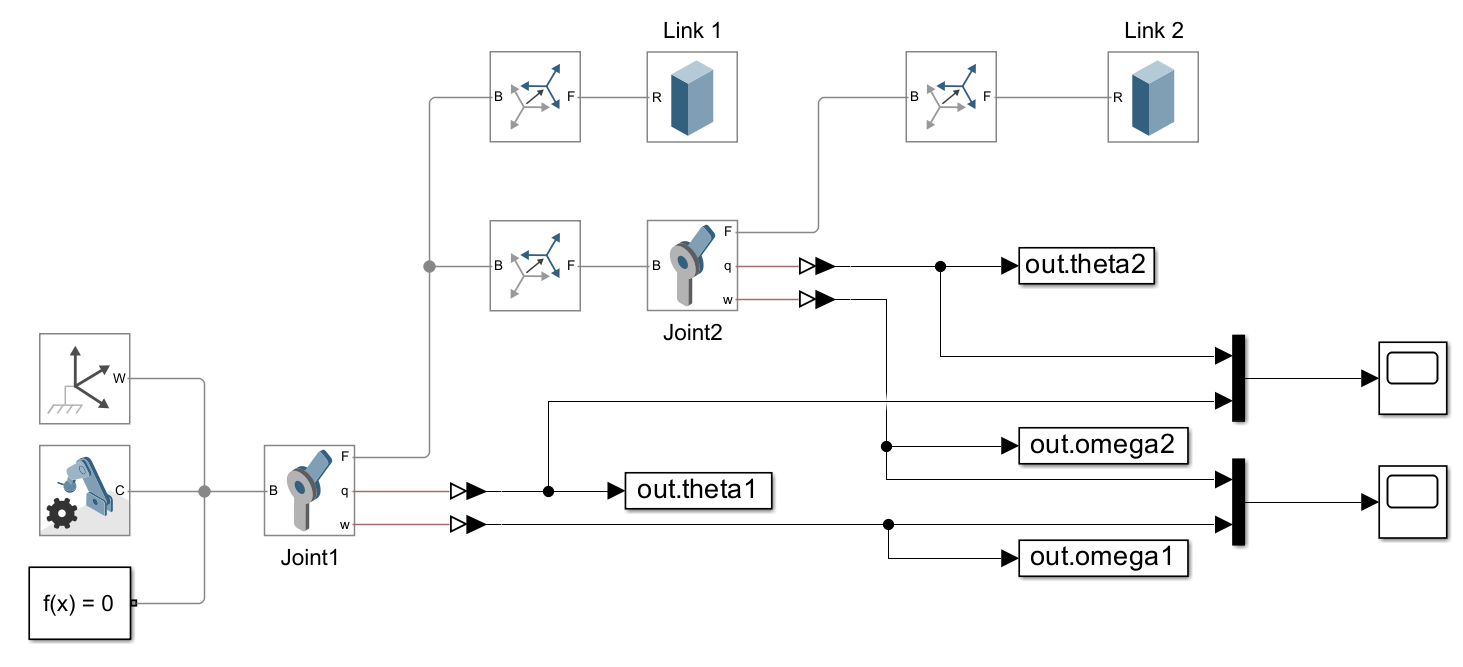

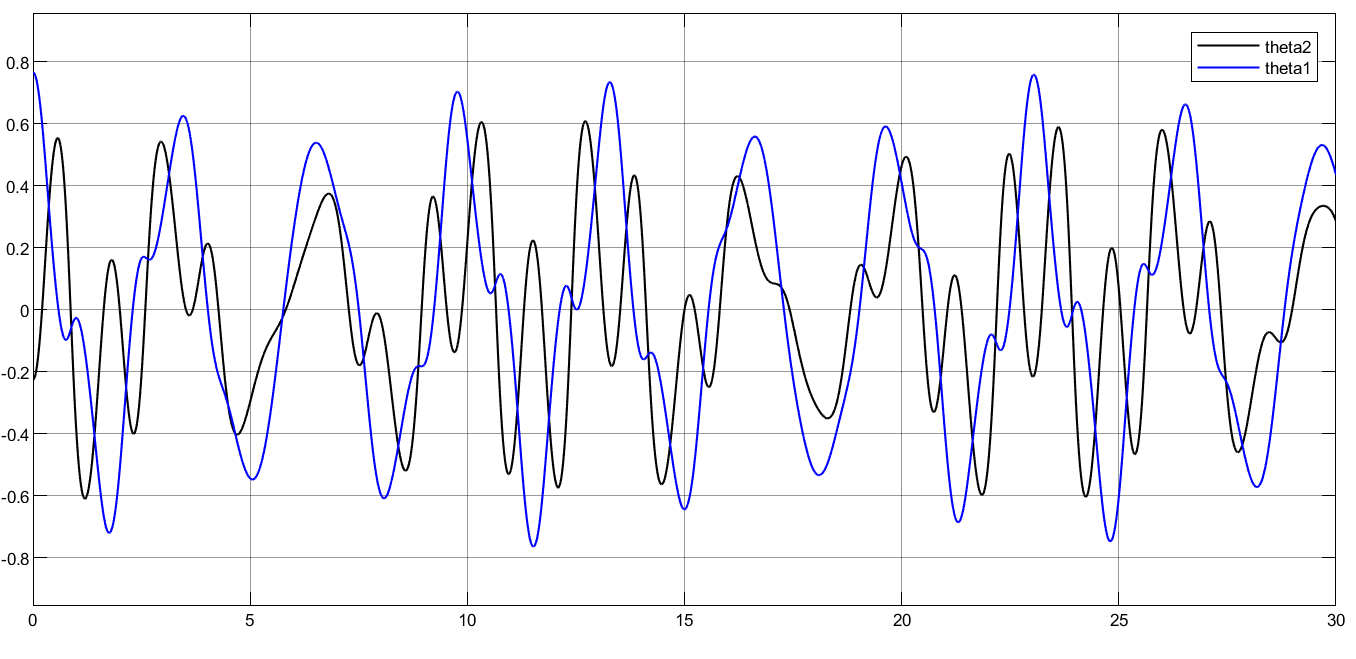

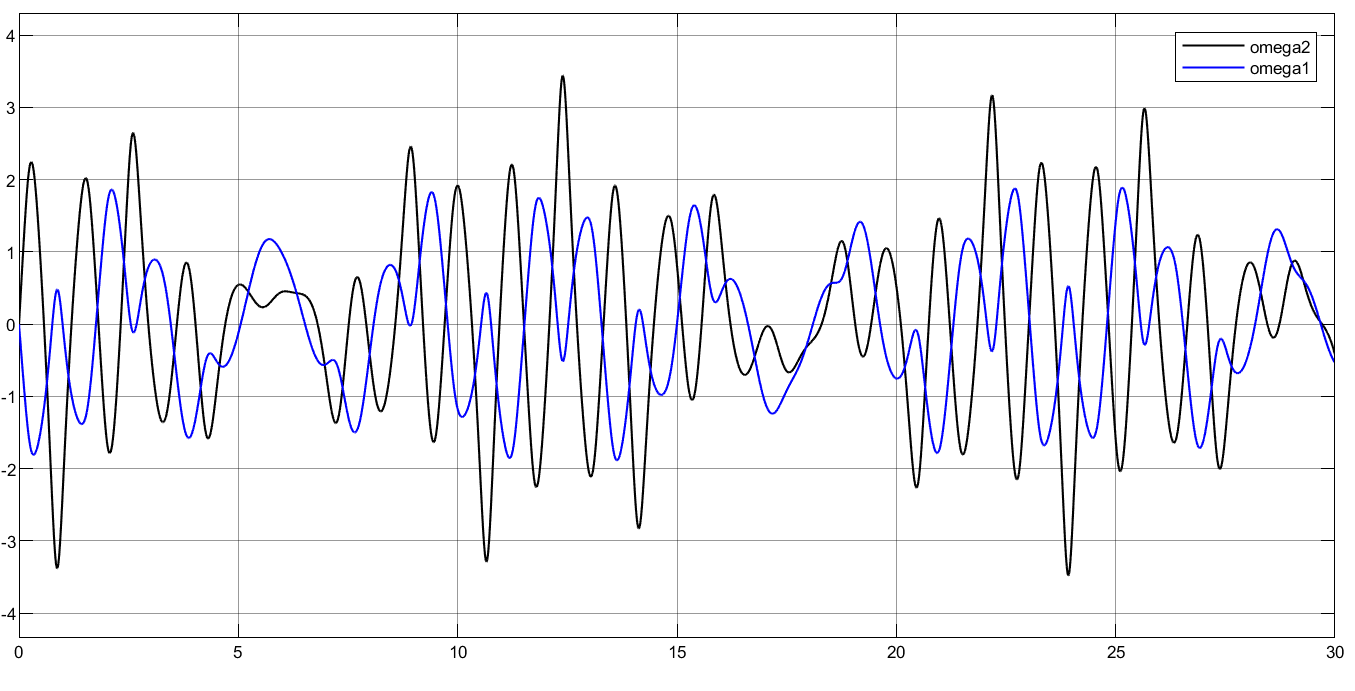

theta1 = out.theta1;
theta2 = out.theta2;
omega1 = out.omega1;
omega2 = out.omega2;

x1 = (l1/2)*sin(theta1);
y1 = -(l1/2)*cos(theta1);
x2 = l1 * sin(theta1) + 0.5 * l2 * sin(theta2);
y2 = -l1 * cos(theta1) + 0.5 * l2 * cos(theta2);

dx1 = (l1/2)*cos(theta1);
dy1 = (l1/2)*sin(theta1);
dx2 = l1 * cos(theta1) - 0.5 * l2 * cos(theta2);
dy2 = -l1 * -sin(theta1) - 0.5 * l2 * sin(theta2);

I1 = (1/12) * m1 * (a1^2 + l1^2); 
I2 = (1/12) * m2 * (a2^2 + l2^2);
K1 = 0.5*(m1*(l1/2)^2 + I1)*(omega1.^2);
K2 = 0.5*m2*((l1^2 + (l2/2)^2 + 2*l1*(l2/2)*cos(theta2)).* ...
    (omega1.^2) + 2*((l2/2)^2 + l1*(l2/2)*cos(theta2)).* ...
    ((omega1).*(omega2)) +((l2/2)^2)*(omega2.^2)) + 0.5*I2*((omega1 + omega2).^2);

## Answers

K_E = K1+K2;
maxK = max(K_E);
maxTheta = [max(theta1) - (pi/2), max(theta2)];
maxdTheta = [max(omega1), max(omega2)];

task.answers.maxK = maxK;
task.answers.maxTheta = maxTheta;
task.answers.maxdTheta = maxdTheta;
task.answers

ans = 包含以下字段的 struct :
         maxK: 30.2573
     maxTheta: [-0.8042 0.6095]
    maxdTheta: [1.8926 3.4427]


hwc.send_task(task)

You have 37 attempts left


ans = 包含以下字段的 struct :
           maxK: 2
       maxTheta: 1
      maxdTheta: 1
    total_score: 4
